# `Ex020 - Processing PES spectra`

For a more in-depth explanation of potential in- and output of those functions, consult the UserGuide.

For external data files, all you need to do is define the **x-axis (binding energy)** and **y-axis (intensity) **and all the fitting tools are available to use. This means you can in principle import any type of data you like, even a text file. To be compatible, all you need to do is define a matlab struct(), for example 'xps_dat{1}', with **two** fields:

- Define the **x-axis data** as:    xps_dat{1}**.xdat**

- Deine the **y-axis data **as:     xps_dat{1}**.ydat**

close all; clear all;
pp          = plot_props

pp = struct with fields:
       fig3x2: [600 400]
       fig4x3: [800 600]
       fig4x5: [400 500]
      fig16x9: [640 360]
     fig16x10: [1280 800]
     fig16x15: [1280 1200]
       fig2x3: [400 600]
       fig3x4: [600 800]
       fig5x4: [500 400]
      fig9x16: [360 640]
     fig10x16: [800 1280]
     fig15x16: [1200 1280]
     fig13x12: [600 650]
       fig4x4: [400 400]
       fig5x5: [500 500]
       fig6x6: [600 600]
       fig7x7: [700 700]
       fig8x8: [800 800]
       fig9x9: [900 900]
     fig10x10: [1000 1000]
       figpos: [100 100]
     fontsize: 9
    ffontsize: 12
       lwidth: 1
      llwidth: 2
        msize: 9
       mmsize: 12
       falpha: 0.5000
      ffalpha: 0.8000
        csize: 3
       ccsize: 6
        clims: [0 1]
          col: [1×1 struct]
       mstyle: [1×1 struct]


path_data   = 'D:\OneDrive\PCC_MS_Project\00_SLS_Software\ARPEScape\ARPEScape-v8.1.0\PESTools_PCC\Examples\Example_Data\ADRESS_data\';
path_save   = 'D:\OneDrive\PCC_MS_Project\00_SLS_Software\ARPEScape\ARPEScape-v8.1.0\PESTools_PCC\Examples\Example_Data_Saved\';

# **(1) XPS Data Processing**

**(A) Loading in the PES data files**

% Load in XPS data
file_names      = {...
    '011_XPS_sAl_350.h5',...
    '012_XPS_sAl_450.h5',...
    '013_XPS_sAl_550.h5',...
    '014_XPS_sAl_650.h5',...
    '015_XPS_sAl_750.h5',...
    '016_XPS_sAl_850.h5',...
    '017_XPS_sAl_950.h5',...
    '018_XPS_sAl_1050.h5',...
    '019_XPS_sAl_1150.h5',...
    };
xps_dat = cell(1,length(file_names));
for i = 1:length(file_names); xps_dat{i} = load_adress_data(file_names{i}, path_data); end

Loading ADRESS data...
Loading ADRESS data...
Loading ADRESS data...
Loading ADRESS data...
Loading ADRESS data...
Loading ADRESS data...
Loading ADRESS data...
Loading ADRESS data...
Loading ADRESS data...


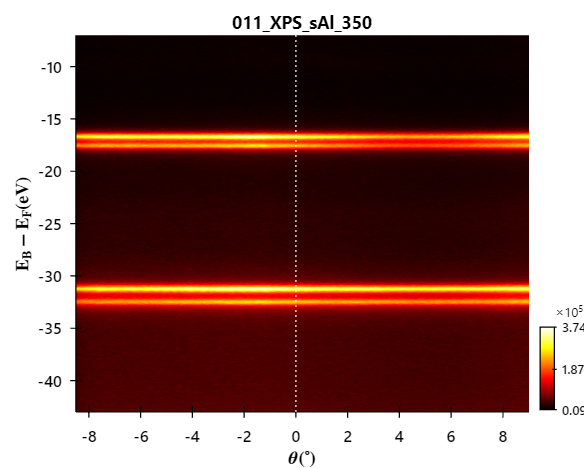

view_arpes_data(xps_dat{1});

**(B) Loading in the Fermi edge reference via gold / copper**

Note, that all PES data should come with a Fermi-edge reference so that the binding energy scale can be properly calibrated.

% Load in Reference data
file_names_ef      = {...
    '011_XPS_350_EF.h5',...
    '012_XPS_450_EF.h5',...
    '013_XPS_550_EF.h5',...
    '014_XPS_650_EF.h5',...
    '015_XPS_750_EF.h5',...
    '016_XPS_850_EF.h5',...
    '017_XPS_950_EF.h5',...
    '018_XPS_1050_EF.h5',...
    '019_XPS_1150_EF.h5',...
    };
xps_ref = cell(1,length(file_names_ef));
for i = 1:length(file_names_ef); xps_ref{i} = load_adress_data(file_names_ef{i}, path_data); end

Loading ADRESS data...
Loading ADRESS data...
Loading ADRESS data...
Loading ADRESS data...
Loading ADRESS data...
Loading ADRESS data...
Loading ADRESS data...
Loading ADRESS data...
Loading ADRESS data...


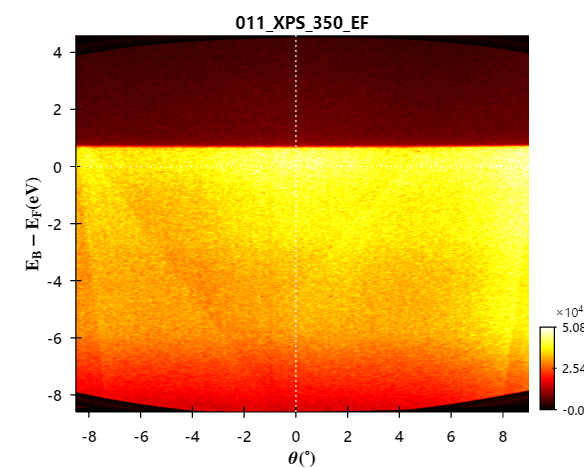

view_arpes_data(xps_ref{1});

**(C) Binding energy alignment to the reference data**

help align_energy;

  [dataStr, dataStr_ref] = align_energy(dataStr, align_args, dataStr_ref, plot_result)
    - #1 - FIRST STEP IN PROCESSING ARPES DATA
    This is a function that will align the 'dataStr' ARPES data-structure 
    to the Fermi-level, a peak, or reference VB or CB state. The energy
    alignment is done using various approaches that the user can select from,
    either using the 'dataStr' or a reference 'dataStr_ref' data file. 
        (1) 'align2ref'  : aligns to some peak or edge reference using MATools AlignEF() function.
        (2) 'fit2ef'    : fits directly to the FDD edge of a reference. 
        (3) 'fit2peak'  : fits directly to some peak feature.
        (4) 'gsv1s'     : global shift via one scan aligned to some peak / edge reference using MATools AlignEF() function.
 
    IN:
    -   dataStr:            data structure of the ARPES data.
    -   align_args:         {1×7} cell of {Type,Scans,eWin, dEWin, dESmooth, feat}.
                                Type: 

- EF alignment


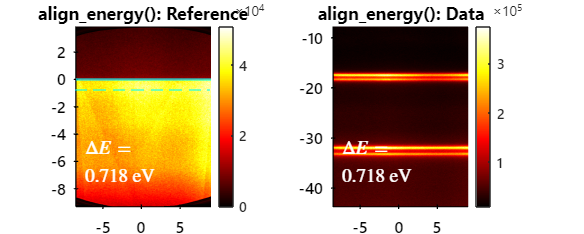

- EF alignment


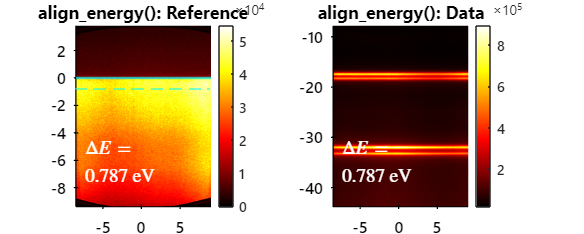

- EF alignment


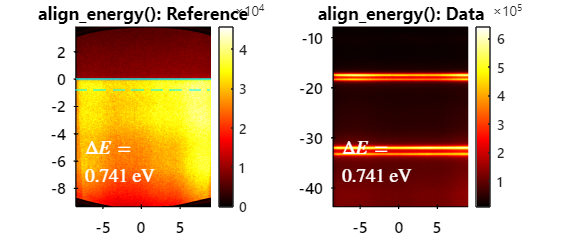

- EF alignment


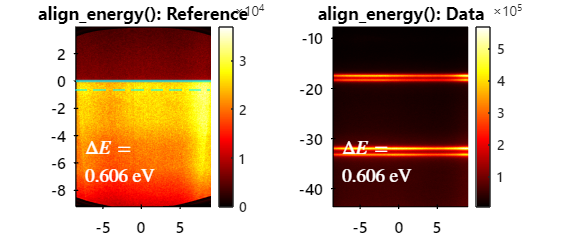

- EF alignment


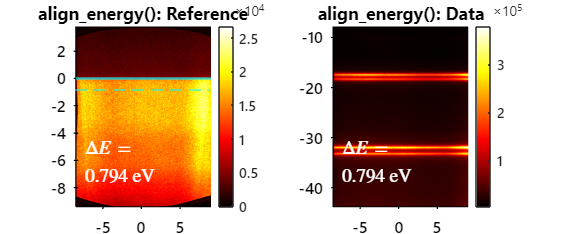

- EF alignment


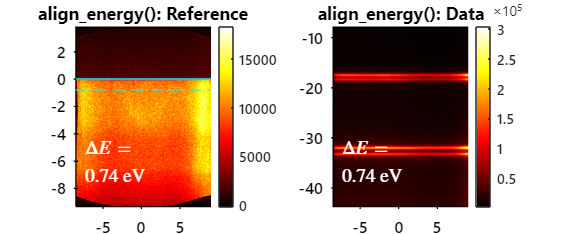

- EF alignment


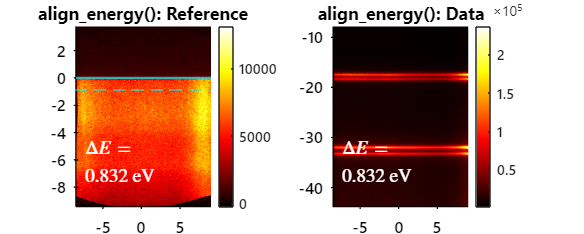

- EF alignment


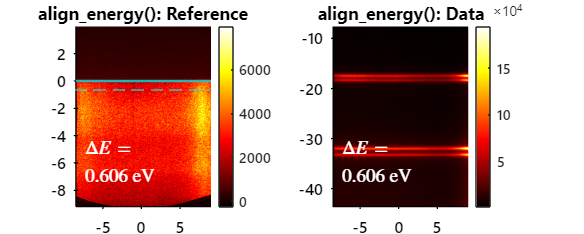

- EF alignment


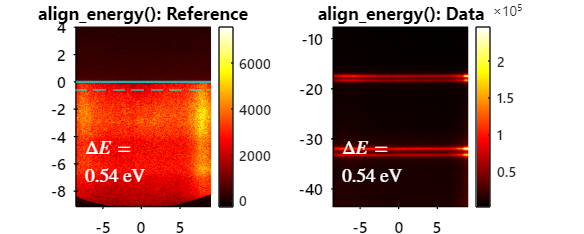

% (1) AUTOMATIC COARSE ALIGNMENT TO THE EDGE OF THE REFERENCE
% -- Coarse alignment of the energy
alignType   = "align2ref";
scan_indxs	= [];
eWin        = 1.00;
dEWin       = 4.00;
dESmooth    = [];
feat        = 'edge';
align_args  = {alignType, scan_indxs, eWin, dEWin, dESmooth, feat};
for i = 1:length(xps_dat)
    [xps_dat{i}, xps_ref{i}] = align_energy(xps_dat{i}, align_args, xps_ref{i}, 1);
end

- Angle integrating

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


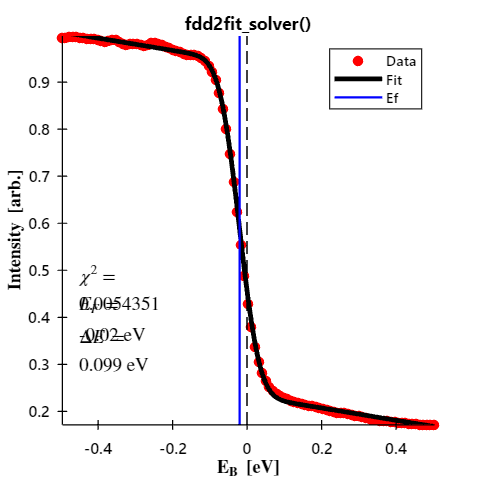

Ef = -0.0200

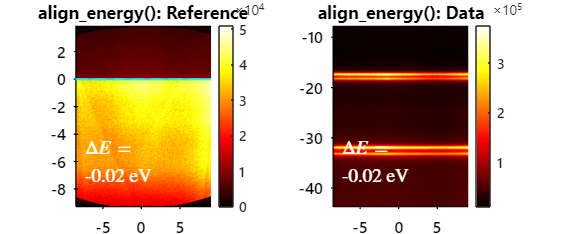

- Angle integrating

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


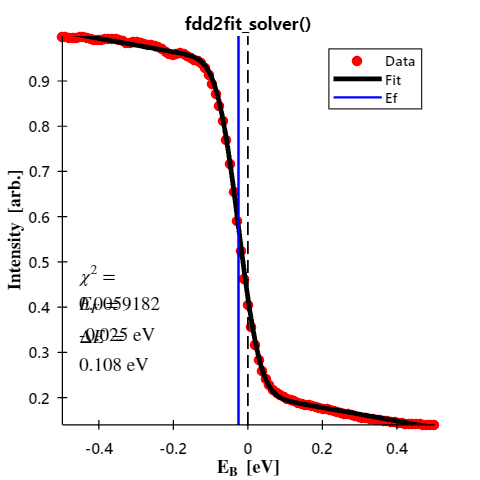

Ef = -0.0251

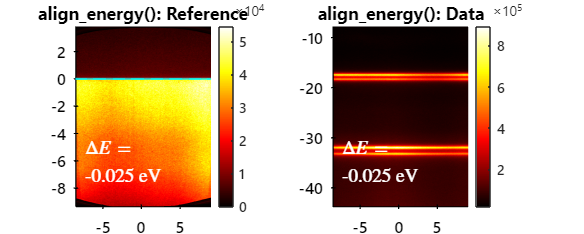

- Angle integrating

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


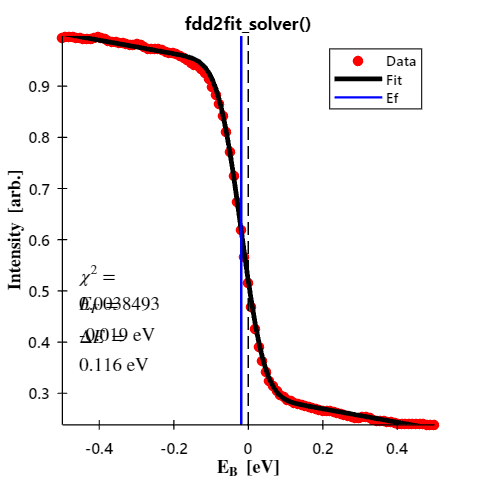

Ef = -0.0190

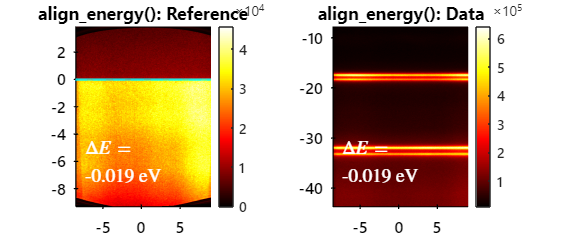

- Angle integrating

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


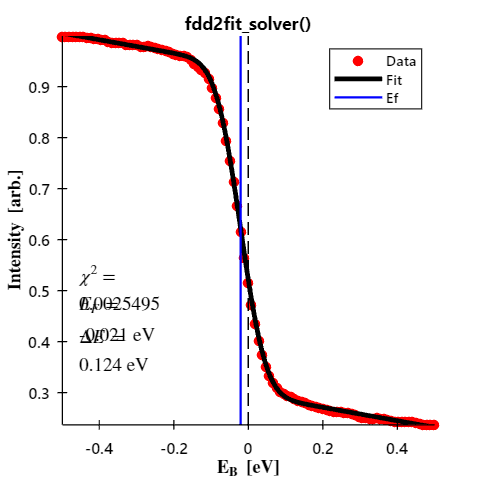

Ef = -0.0206

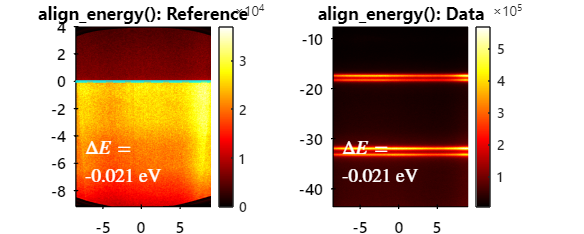

- Angle integrating

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


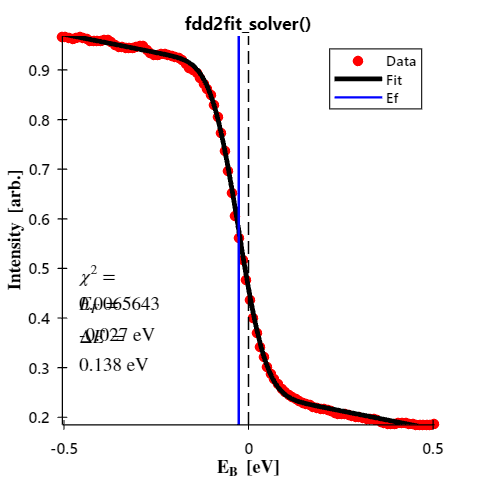

Ef = -0.0267

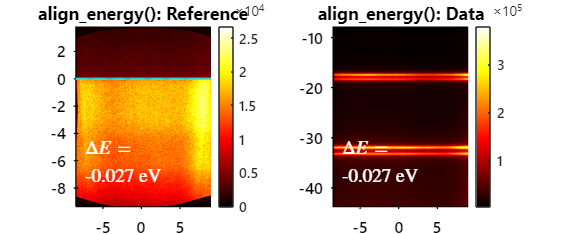

- Angle integrating

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


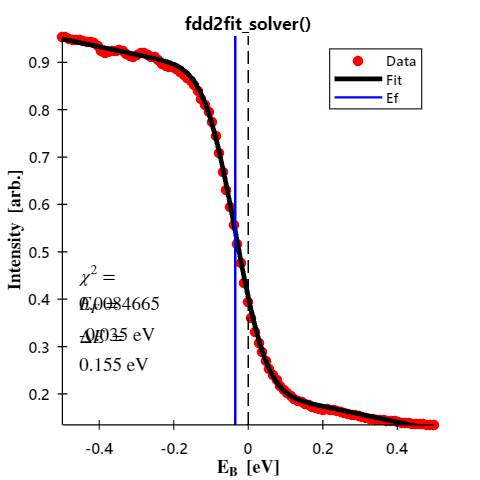

Ef = -0.0349

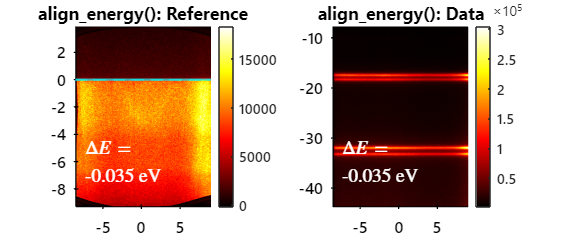

- Angle integrating

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


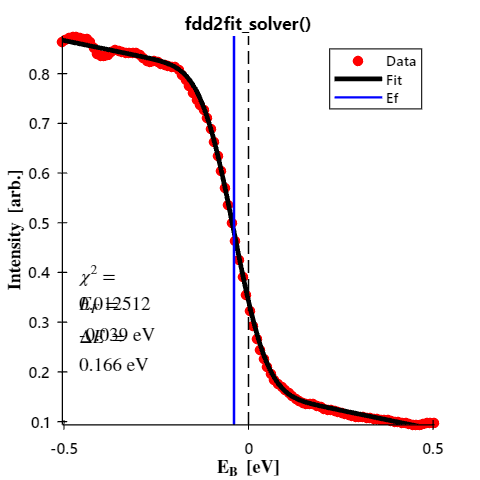

Ef = -0.0395

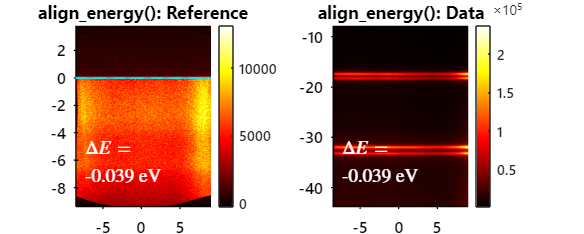

- Angle integrating

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


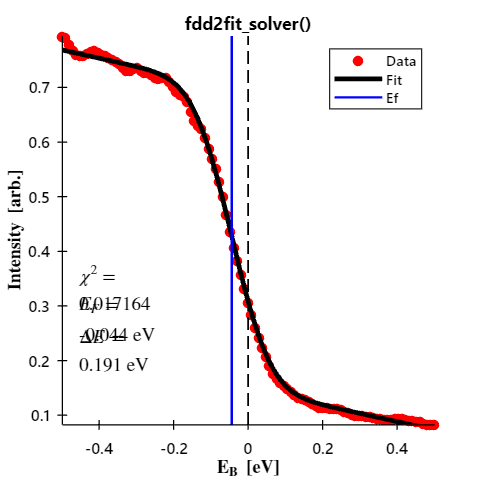

Ef = -0.0439

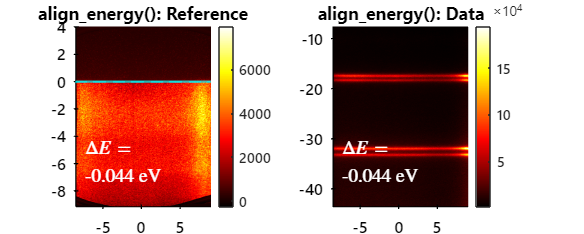

- Angle integrating

Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


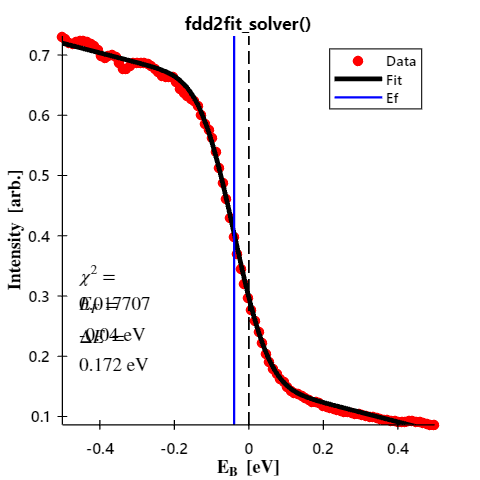

Ef = -0.0397

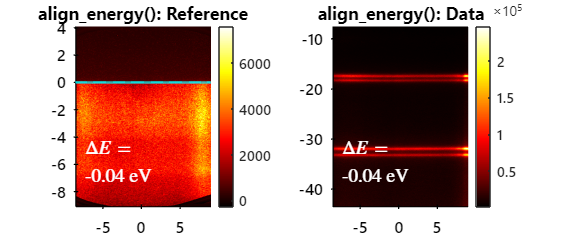

% (2) FITTING TO THE FDD WITH FINE ALIGNMENT
alignType   = "fit2ef"; 
scan_indxs	= [];
eWin        = 0.00;
dEWin       = 0.50;
dESmooth    = [];
feat        = 'edge';
align_args  = {alignType, scan_indxs, eWin, dEWin, dESmooth, feat};
for i = 1:length(xps_dat)
    xps_dat{i}  = align_energy(xps_dat{i}, align_args, xps_ref{i}, 1); 
end

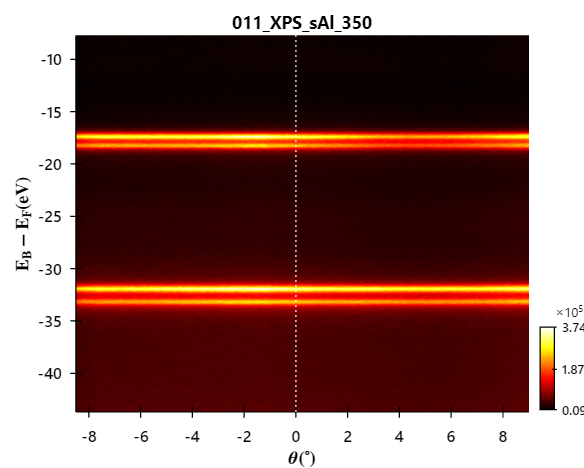

view_arpes_data(xps_dat{1});

**(D) Extracting the angle-integrated XPS spectra**

for i = 1:length(xps_dat)
    cutWin      = 0.95*[min(xps_dat{i}.raw_tht(:)), max(xps_dat{i}.raw_tht(:))];      % Integration window of the cut to be made.
    xps_args    = {cutWin};
    [xps_dat{i}, ~] = pes_extract_data(xps_dat{i}, xps_args, 0); 
end

- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation


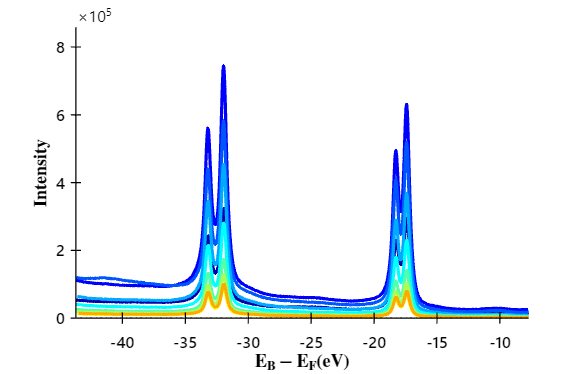

view_pes_data(xps_dat);

**(E) Extracting the principal peak position**

1) x = -17.40, y = 295369.68 


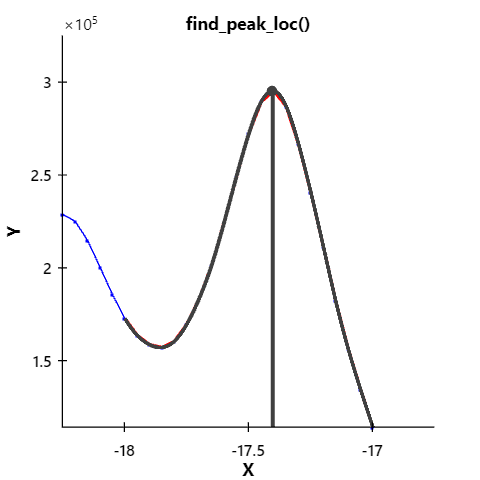

% -- Extracting the energy and intensity of the peak positions
xWin       = -17.5 + 0.5*[-1,1];
for i = 1:length(xps_dat)
    if i == 1;  [xps_dat{i}.peak_loc, xps_dat{i}.peak_int] = find_peak_loc(xps_dat{i}.xdat, xps_dat{i}.ydat, xWin, 'spline', 1); 
    else;       [xps_dat{i}.peak_loc, xps_dat{i}.peak_int] = find_peak_loc(xps_dat{i}.xdat, xps_dat{i}.ydat, xWin, 'spline', 0); 
    end
end

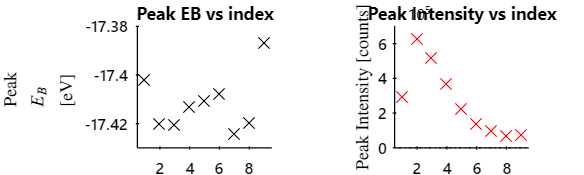

% -- Plotting the comparison
fig1 = figure();
fig1.Position(3) = 2.0*500;
fig1.Position(4) = 1.0*300;
% -- Plotting the Peak Eb position vs Photon Energy
subplot(121); hold on;
for i = 1:length(xps_dat); plot(i, xps_dat{i}.peak_loc, 'kx-', 'markersize', 10); end
gca_props(); xlim([0.5, length(xps_dat)+0.5]);
title('Peak EB vs index');
ylabel('Peak $$E_{B}$$ [eV]', 'interpreter', 'latex');
% -- Plotting the Peak Intensity vs Photon Energy
subplot(122); hold on;
for i = 1:length(xps_dat); plot(i, xps_dat{i}.peak_int, 'rx-', 'markersize', 10); end
gca_props(); xlim([0.5, length(xps_dat)+0.5]);
title('Peak Intensity vs index');
ylabel('Peak Intensity [counts]', 'interpreter', 'latex');

**(F) Normalising the XPS data**

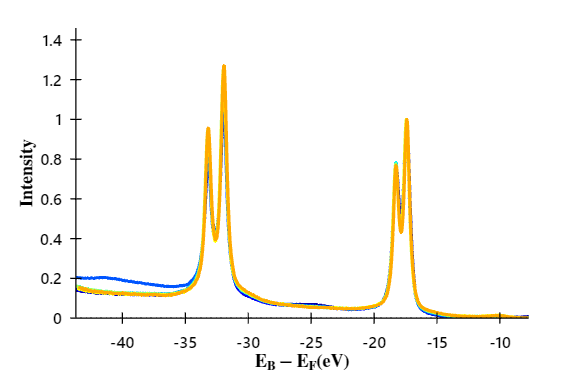

for i = 1:length(xps_dat)
    eWin            = xps_dat{i}.peak_loc;      % approximate Eb position of a peak in the spectrum to normalise to.
    dEWin           = 1.0;                      % can be empty []. Single, constant value that defines the width of the approximate Eb position
    norm_args       = {eWin, dEWin};
    xps_dat{i}.ydat = pes_norm2peak(xps_dat{i}.xdat, xps_dat{i}.ydat, norm_args, 0);
end
view_pes_data(xps_dat);

**(G) Cropping the XPS data**

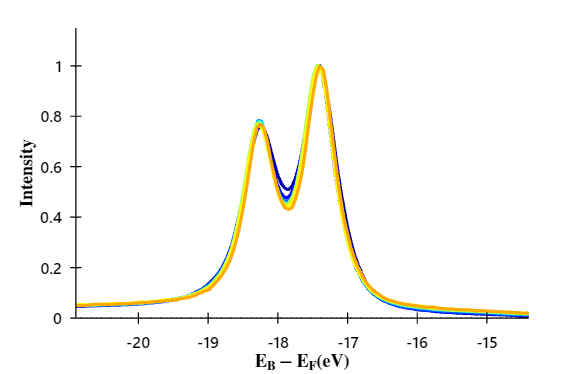

ebLims = xps_dat{1}.peak_loc + [-3.5, 3.0];
for i = 1:length(xps_dat)
    [~, xps_dat{i}.xdat, xps_dat{i}.ydat] = data_crop2D([], xps_dat{i}.xdat, xps_dat{i}.ydat, [], ebLims);
end
view_pes_data(xps_dat);

**(H) View the final XPS data**

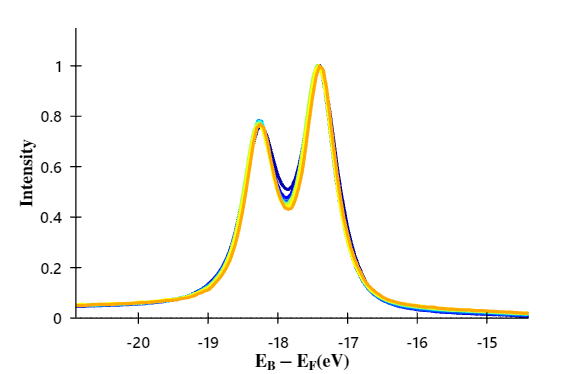

view_pes_data(xps_dat);